clc 
clear
addpath("Functions\")
yalmip('clear')

**State Space formulation and discretization**

syms beta(t) tau w
linBeta = deg2rad(0);%% Starh with beta at 0 degrees linearization
winDir = 5*pi/4;
muWind = 1.0;
[A_cont,B_cont] = Linearization_Wind(linBeta,beta,tau,winDir,w,muWind); 
% 
 C_cont=[0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0;
        1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
        0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;]

C_cont =      0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% 
%   C_cont=eye(length(A_cont));
% C_cont(5,:) = [] 
D =0;


l=18;

h = 0.2; % Discrete time step,
[A,B,C] = Forward_BackEuler(A_cont,B_cont,C_cont,h)

A =     1.0000         0         0    0.0151    0.0000         0   -0.0000   -0.0000    0.2001   -0.0000    0.0000    0.0015    0.0000         0   -0.0000   -0.0000    0.0012
         0    1.0000         0   -0.0000    0.0002         0   -0.0000    0.0006    0.0000    0.1984    0.0000   -0.0000    0.0000         0   -0.0000    0.0001    0.0000
         0         0    1.0000    0.0005   -0.0000         0   -0.0003    0.0000    0.0000    0.0000    0.1982   -0.0001   -0.0000         0   -0.0000    0.0000    0.0000
         0         0         0    0.9980    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.1997    0.0000         0    0.0000   -0.0000   -0.0001
         0         0         0   -0.2384    1.0032         0   -0.0000   -0.0033    0.0000   -0.0036    0.0000   -0.0238    0.2048         0   -0.0000   -0.0003    0.0048
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    0.2000 

B = 1.0e-03 *

    0.0076    0.0000   -0.0000    0.0000    0.0076    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0075    0.0000   -0.0000    0.0000    0.0075    0.0000
    0.0000    0.0043    0.0000    0.0043    0.0000    0.0043    0.0000    0.0043
   -0.0004   -0.0000   -0.0000   -0.0000   -0.0004   -0.0000   -0.0000   -0.0000
    0.0001    0.0000   -0.0432    0.0000    0.0001    0.0000   -0.0432    0.0000
         0    0.0001         0         0         0   -0.0001         0         0
         0         0         0    0.0001         0         0         0   -0.0001
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0757    0.0003   -0.0000    0.0003    0.0757    0.0003   -0.0000    0.0003
    0.0000    0.0000    0.0751    0.0000   -0.0000    0.0000    0.0751    0.0000


C =      0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



sys = ss(A,B,C,D);
n = length(A);

simTime = 60/h;

**Wind Paramaters**

muw = 1.0;

ti = 0.25; %turbulence itencity

CV = ti*muw;

 
%Turbulent part
Wt= zeros(1,simTime);
wp = (muw*pi)/(2*340.2);
at = exp(-wp*h)

at = 0.9991

stdt= (ti *muw*sqrt(1-at^2));

%Slow Part
q = 2^2/600 ; %slow part changinf by 2m/s over 10 min.
stdw = sqrt(h*q);
Ws= zeros(1,simTime);
Ws(50) = 2.0;


W = zeros(1,simTime)

W =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


**MPC Formulation**


ref =0;
Hp = 25;
Hu = 1;
%Lifting the dynamics to be expressed in terms of delta u.
[ALift, BuLift, BduLift, Psi, Upsilon_B, Theta] = MPCLift(A, B, C ,Hp, Hu)

Condition of:
 Psi: 208406959459144055866261504.000000
 Upsilon: 38570191715917905920.000000 
 Theta: 38570191715917905920.000000

ALift = 1.0e+03 *

    0.0010         0         0    0.0000    0.0000         0   -0.0000   -0.0000    0.0002   -0.0000    0.0000    0.0000    0.0000         0   -0.0000   -0.0000    0.0000
         0    0.0010         0   -0.0000    0.0000         0   -0.0000    0.0000    0.0000    0.0002    0.0000   -0.0000    0.0000         0   -0.0000    0.0000    0.0000
         0         0    0.0010    0.0000   -0.0000         0   -0.0000    0.0000    0.0000    0.0000    0.0002   -0.0000   -0.0000         0   -0.0000    0.0000    0.0000
         0         0         0    0.0010    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0002    0.0000         0    0.0000   -0.0000   -0.0000
         0         0         0   -0.0002    0.0010         0   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0002         0   -0.0000   -0.0000    0.0000
         0         0         0         0         0    0.0010         0         0         0         0         0         0      

BuLift =     0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000


BduLift =     0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000


Psi = 1.0e+03 *

         0         0         0    0.0010    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0002    0.0000         0    0.0000   -0.0000   -0.0000
         0         0         0   -0.0024    0.0000         0   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0002    0.0010         0   -0.0000   -0.0000    0.0000
    0.0010         0         0    0.0000    0.0000         0   -0.0000   -0.0000    0.0002   -0.0000    0.0000    0.0000    0.0000         0   -0.0000   -0.0000    0.0000
         0    0.0010         0   -0.0000    0.0000         0   -0.0000    0.0000    0.0000    0.0002    0.0000   -0.0000    0.0000         0   -0.0000    0.0000    0.0000
         0         0         0    0.0010    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0000         0    0.0000   -0.0000   -0.0000
         0         0         0   -0.0049    0.0001         0   -0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0010    0.00

Upsilon_B =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0004    0.0000    0.0000    0.0000   -0.0004    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0009    0.0000    0.0000    0.0000   -0.0009    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0014    0.0000    0.0000    0.0000   -0.0014    0.0000


Theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0004    0.0000    0.0000    0.0000   -0.0004    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0009    0.0000    0.0000    0.0000   -0.0009    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0014    0.0000    0.0000    0.0000   -0.0014    0.0000



p = size(B,2);
m = size(C,1)

m = 4



%Tune values from Q and R 
QLift = 1*eye(Hp*m);

values = [1;1;100000;100000]; % The values to be placed on the diagonal
len = length(values); % Length of the values vector

for i = 1:Hp
        for j = 1:len
            QLift((i-1)*m+j, (i-1)*m+j) = values(j);
        end
end




RLift = 1*eye(Hu*p);
rho =ones(1,2);
rho(1) = 1

rho =      1     1


rho(2) = 100000

rho =            1      100000




duPlot = zeros(p,simTime);
Xplant = zeros(n,simTime);
Yplant = zeros(n,simTime);
x = zeros(n,simTime);
u = zeros(p,simTime);


du = sdpvar(8*Hu,1);
slack = sdpvar(2,1);

 Tau = [ones(Hp*m,1)]

Tau =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



% for i=1:Hp
%     Tau((i-1)*m+1:i*m) = [0;0;15;0;0];
% end
constraints = [];
% for i=1:Hp
%     Tau((i-1)*m+1:i*(m)) = [0;0;15;0;30;0;0];
% end

for i=1:Hp
    % Tau((i-1)*m+1:i*(m)) = [0;0;15;0;0;0;0;0;0;0;0;0;0;0;0;0];
    Tau((i-1)*m+1:i*(m)) = [0; 0; 10; 10];
end
% Xplant(:,1) = [0 0 0 deg2rad(10) 0 0 0 0]';
Xplant(:,1) = [0 0 15 deg2rad(0) deg2rad(0) 0 0 0 0 0 0 0 0 0 0 0 0]';


noise = 1;  
f = waitbar(0,'Please wait...');
tic

lin_count = 0

lin_count = 0


for i=2:(simTime)
    % Calculate the Plant

    %Wind speed stuff
   
    if i > 50 && i < 250

        et = normrnd(0,stdw);
        Ws(i) = Ws(i-1)+ et;

        es = normrnd(0,stdt^2);
        Wt(i) = at * Wt(i-1)+ es;

        W(i)  = Ws(i) + Wt(i);

        if W(i) <=0
            W(i) = 0;
        end
    end
   Xplant(:,i) = A * Xplant(:,i-1) + B*u(:,i-1);
    Xplant(17,i-1) = W(i);
    Xplant(:,i) = A * Xplant(:,i-1) + B*u(:,i-1);

    if abs(linBeta-Xplant(5,i))>deg2rad(1)
        
        lin_count= lin_count+1;
        waitbar(i/simTime,f, sprintf('New linearization point. Total: %i', lin_count));
       linBeta = Xplant(5,i);
       [A_cont,B_cont] = Linearization_Wind(linBeta,beta,tau,winDir,w,muWind); 
       [A,B,C] = Forward_BackEuler(A_cont,B_cont,C_cont,h);
       [ALift, BuLift, BduLift, Psi, Upsilon, Theta] = MPCLift(A, B, C ,Hp, Hu);
    end
    xopt = Xplant(:,i); % Seh the current state as the starting point for the optimization.
    % xopt = y0';

    %z = Psi * xopt + Upsilon_B * u(:,i-1)+ Upsilon_W * w(i) + Theta * du;

    z = Psi * xopt + Upsilon_B * u(:,i-1) + Theta * du;
    objective = ( (z - Tau)' * QLift * (z - Tau) + du' * RLift * du + rho * slack);
     constraints1 = [abs(z(1:m:end)) <= deg2rad(10) + slack(1),abs(z(2:m:end)) <= deg2rad(2) + slack(2),abs(u(:,i-1)+du(1:p))<= [200;200;200;200;200;200;200;200],slack >= 0]
    % constraints1 = [abs(z(4:m:end)) <= deg2rad(10) + slack(1),abs(z(13:m:end)) <= deg2rad(10) + slack(2),abs(u(:,i-1)+du(1:p))<= [200;200;200;200;200;200;200;200],slack >= 0]
    constraints2 = []

    ops = sdpsettings('solver','ipopt');
    ops.verbose = 0;
    % ops.verbose = 0; % makes yalmip quiet
    optimize([constraints1,constraints2],objective, ops);


    duPlot(:,i) = du(1:p);
    waitbar(i/simTime,f, sprintf('Simulating step: %i of %i',i, simTime));
    u(:,i) = u(:,i-1) + du(1:p);
    
end

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 409993528041493421317160960.000000
 Upsilon: 8214723725502499840.000000 
 Theta: 8214723725502499840.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 125517775315447403687968768.000000
 Upsilon: 9767050844397047808.000000 
 Theta: 9767050844397047808.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 24353189832679905459961856.000000
 Upsilon: 18496180764777103360.000000 
 Theta: 18496180764777103360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 35813342027712775497711616.000000
 Upsilon: 72669487143082295296.000000 
 Theta: 72669487143082295296.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 24124427666795823923986432.000000
 Upsilon: 176075001182932402176.000000 
 Theta: 176075001182932402176.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 95202075900993384103280640.000000
 Upsilon: 38744996203384086528.000000 
 Theta: 38744996203384086528.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 29014701471085753589039104.000000
 Upsilon: 5022236529932606464.000000 
 Theta: 5022236529932606464.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 25698393525676978703695872.000000
 Upsilon: 1840386211257661696.000000 
 Theta: 1840386211257661696.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 457114135972712859551399936.000000
 Upsilon: 8991457054558990336.000000 
 Theta: 8991457054558990336.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 24435533218806181633458176.000000
 Upsilon: 2853957583797725184.000000 
 Theta: 2853957583797725184.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 223316492101952611884728320.000000
 Upsilon: 4385567720477244928.000000 
 Theta: 4385567720477244928.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3868083464258787773251584.000000
 Upsilon: 3233182415622103040.000000 
 Theta: 3233182415622103040.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3048441677086021799378944.000000
 Upsilon: 3687261556288638976.000000 
 Theta: 3687261556288638976.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 15462832787583607555227648.000000
 Upsilon: 3113477654419921920.000000 
 Theta: 3113477654419921920.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7729068724644794505101312.000000
 Upsilon: 7319006441423479808.000000 
 Theta: 7319006441423479808.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9635911312157410037071872.000000
 Upsilon: 16559427882747645952.000000 
 Theta: 16559427882747645952.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 13054519625497873563516928.000000
 Upsilon: 6324209473788265472.000000 
 Theta: 6324209473788265472.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6032395775642311449378816.000000
 Upsilon: 3578510348205806592.000000 
 Theta: 3578510348205806592.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 18255172914068980005601280.000000
 Upsilon: 2850649006001841152.000000 
 Theta: 2850649006001841152.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 15918831462302290592923648.000000
 Upsilon: 4349928007934524928.000000 
 Theta: 4349928007934524928.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4402652056416928692961280.000000
 Upsilon: 2551929855729189376.000000 
 Theta: 2551929855729189376.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4875322414988612524310528.000000
 Upsilon: 1515791378066824448.000000 
 Theta: 1515791378066824448.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 43522443478970163018072064.000000
 Upsilon: 5202563435116295168.000000 
 Theta: 5202563435116295168.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 25516578169580605853925376.000000
 Upsilon: 34404898826175811584.000000 
 Theta: 34404898826175811584.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1736486952383328619010719744.000000
 Upsilon: 102502302325713977344.000000 
 Theta: 102502302325713977344.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 159540544735275533377470464.000000
 Upsilon: 56068965774057971712.000000 
 Theta: 56068965774057971712.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 174044001572392484774871040.000000
 Upsilon: 26724922901497028608.000000 
 Theta: 26724922901497028608.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 361797934731756930628321280.000000
 Upsilon: 6448420162206152704.000000 
 Theta: 6448420162206152704.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 27063868674356352798162944.000000
 Upsilon: 24125339646932221952.000000 
 Theta: 24125339646932221952.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 94128480356373613072351232.000000
 Upsilon: 17976091697591869440.000000 
 Theta: 17976091697591869440.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 70226500495351619939991552.000000
 Upsilon: 40468344534414671872.000000 
 Theta: 40468344534414671872.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 147101594927540507257077760.000000
 Upsilon: 13208795430819082240.000000 
 Theta: 13208795430819082240.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 44860632865142148131979264.000000
 Upsilon: 17013349176448458752.000000 
 Theta: 17013349176448458752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 282179790902289252527112192.000000
 Upsilon: 83096905556219215872.000000 
 Theta: 83096905556219215872.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 87446134012223076685578240.000000
 Upsilon: 68539194524176457728.000000 
 Theta: 68539194524176457728.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 15771865333008083766476800.000000
 Upsilon: 36993478131610353664.000000 
 Theta: 36993478131610353664.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 620734735438687668312997888.000000
 Upsilon: 74666196585996091392.000000 
 Theta: 74666196585996091392.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 19872623621148359614529536.000000
 Upsilon: 38903790070154690560.000000 
 Theta: 38903790070154690560.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 31970559643244197157273600.000000
 Upsilon: 3393342884490675200.000000 
 Theta: 3393342884490675200.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 18406026667430037004746752.000000
 Upsilon: 6735803604032587776.000000 
 Theta: 6735803604032587776.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4325113602138553446301696.000000
 Upsilon: 7863890639731228672.000000 
 Theta: 7863890639731228672.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 186755160086388048062840832.000000
 Upsilon: 3073934927696046080.000000 
 Theta: 3073934927696046080.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 192824779476440623087616.000000
 Upsilon: 2569079295091136000.000000 
 Theta: 2569079295091136000.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6750823236038933740519424.000000
 Upsilon: 4702197867162631168.000000 
 Theta: 4702197867162631168.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 146680133395900829121118208.000000
 Upsilon: 5139938427071619072.000000 
 Theta: 5139938427071619072.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4539277940800931290415104.000000
 Upsilon: 4164202914273184768.000000 
 Theta: 4164202914273184768.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 11257709967224485401591808.000000
 Upsilon: 7706268524261327872.000000 
 Theta: 7706268524261327872.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1518866837347603144769536.000000
 Upsilon: 21904862186356330496.000000 
 Theta: 21904862186356330496.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1692764862927732056522752.000000
 Upsilon: 5468833105692794880.000000 
 Theta: 5468833105692794880.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6302597705235965342121984.000000
 Upsilon: 2592110703340641792.000000 
 Theta: 2592110703340641792.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5135923168065944069079040.000000
 Upsilon: 3292630584609874944.000000 
 Theta: 3292630584609874944.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 13242103631116457522233344.000000
 Upsilon: 13797408990593697792.000000 
 Theta: 13797408990593697792.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3246816891294733031178240.000000
 Upsilon: 3147067075353180160.000000 
 Theta: 3147067075353180160.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 11063625383522313581887488.000000
 Upsilon: 1976868126351910144.000000 
 Theta: 1976868126351910144.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9658457806320344519147520.000000
 Upsilon: 2032225225414196480.000000 
 Theta: 2032225225414196480.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 70792676346225376305872896.000000
 Upsilon: 9621237791533770752.000000 
 Theta: 9621237791533770752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 186169622842677601496989696.000000
 Upsilon: 26098262660947218432.000000 
 Theta: 26098262660947218432.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 227064739055611916752781312.000000
 Upsilon: 182199018752329711616.000000 
 Theta: 182199018752329711616.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 218489261700217335791484928.000000
 Upsilon: 47976495763953049600.000000 
 Theta: 47976495763953049600.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 32874951905093632359661568.000000
 Upsilon: 3676457908344935424.000000 
 Theta: 3676457908344935424.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3618279903302315375853568.000000
 Upsilon: 2530229343117413376.000000 
 Theta: 2530229343117413376.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3628541477787330727116800.000000
 Upsilon: 1798477318161395200.000000 
 Theta: 1798477318161395200.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 21524576508381695901171712.000000
 Upsilon: 3922120099331238912.000000 
 Theta: 3922120099331238912.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 19349023532177979525300224.000000
 Upsilon: 10964391666834055168.000000 
 Theta: 10964391666834055168.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3958232661404768909918208.000000
 Upsilon: 7689816044258206720.000000 
 Theta: 7689816044258206720.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 959292487795589322375168.000000
 Upsilon: 2773528089408968192.000000 
 Theta: 2773528089408968192.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 45562682297193543524941824.000000
 Upsilon: 3433497619278740992.000000 
 Theta: 3433497619278740992.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 22793202971102488565907456.000000
 Upsilon: 2303863877010798848.000000 
 Theta: 2303863877010798848.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 284809918372506579234717696.000000
 Upsilon: 1535390363110954496.000000 
 Theta: 1535390363110954496.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 104606945212180286566039552.000000
 Upsilon: 3064727281185220096.000000 
 Theta: 3064727281185220096.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 33471571293557425340153856.000000
 Upsilon: 3409366144228494336.000000 
 Theta: 3409366144228494336.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 74463616875178154564517888.000000
 Upsilon: 5270156022421783552.000000 
 Theta: 5270156022421783552.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 170591637226023713178124288.000000
 Upsilon: 42393467271936294912.000000 
 Theta: 42393467271936294912.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 438507115060390927162933248.000000
 Upsilon: 115077859374028587008.000000 
 Theta: 115077859374028587008.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 169707207876417963434180608.000000
 Upsilon: 7065052932127456256.000000 
 Theta: 7065052932127456256.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 56128752268507507335364608.000000
 Upsilon: 13700161671105978368.000000 
 Theta: 13700161671105978368.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 50804588044475274968956928.000000
 Upsilon: 1383697897416995840.000000 
 Theta: 1383697897416995840.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 69851481752586275973496832.000000
 Upsilon: 3564855805129054208.000000 
 Theta: 3564855805129054208.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9574091230500304120184832.000000
 Upsilon: 7827531473602461696.000000 
 Theta: 7827531473602461696.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 17479573773134035383484416.000000
 Upsilon: 1025869573695245312.000000 
 Theta: 1025869573695245312.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 315265529626099143386595328.000000
 Upsilon: 3890535073447134208.000000 
 Theta: 3890535073447134208.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 15737774792273743094743040.000000
 Upsilon: 2835963042414779392.000000 
 Theta: 2835963042414779392.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 137010002958099687116111872.000000
 Upsilon: 10120963791179149312.000000 
 Theta: 10120963791179149312.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 121248936245165062109528064.000000
 Upsilon: 13168774371409352704.000000 
 Theta: 13168774371409352704.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 467652752070221772942737408.000000
 Upsilon: 52403096231614930944.000000 
 Theta: 52403096231614930944.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 62730117688111118715715584.000000
 Upsilon: 14133632672797429760.000000 
 Theta: 14133632672797429760.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 19197510241728085603909632.000000
 Upsilon: 4503182175099204096.000000 
 Theta: 4503182175099204096.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5012063616421365219852288.000000
 Upsilon: 3022196839831605248.000000 
 Theta: 3022196839831605248.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3208123540993342103879680.000000
 Upsilon: 6558262926632338432.000000 
 Theta: 6558262926632338432.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1871219969590597039161344.000000
 Upsilon: 4453185964155129344.000000 
 Theta: 4453185964155129344.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 22824420354573726503665664.000000
 Upsilon: 3305594368223952896.000000 
 Theta: 3305594368223952896.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 31868347252491505631232000.000000
 Upsilon: 5362835015007854592.000000 
 Theta: 5362835015007854592.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 285832157783367445584543744.000000
 Upsilon: 38760720063774769152.000000 
 Theta: 38760720063774769152.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 34074212034566664069578752.000000
 Upsilon: 23132435208567406592.000000 
 Theta: 23132435208567406592.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 17874268511718825521053696.000000
 Upsilon: 2927841924134170112.000000 
 Theta: 2927841924134170112.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9737236121221614849228800.000000
 Upsilon: 2058636655872225536.000000 
 Theta: 2058636655872225536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3523748381547528747745280.000000
 Upsilon: 3250723275387344896.000000 
 Theta: 3250723275387344896.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7741272342036625206804480.000000
 Upsilon: 2185523320743744256.000000 
 Theta: 2185523320743744256.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 60180589775244756319731712.000000
 Upsilon: 3815544552979542528.000000 
 Theta: 3815544552979542528.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1963840644598596304547872768.000000
 Upsilon: 75803893778942689280.000000 
 Theta: 75803893778942689280.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 195871927793178594884190208.000000
 Upsilon: 20774863832838352896.000000 
 Theta: 20774863832838352896.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 72444968166635942111608832.000000
 Upsilon: 3021796862056088576.000000 
 Theta: 3021796862056088576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9466826591641650277122048.000000
 Upsilon: 6742582386231611392.000000 
 Theta: 6742582386231611392.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4778306348670843128643584.000000
 Upsilon: 2312012382084417536.000000 
 Theta: 2312012382084417536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 13502989537662708949712896.000000
 Upsilon: 4394269919242536448.000000 
 Theta: 4394269919242536448.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 42099706447061182442373120.000000
 Upsilon: 100480622759451738112.000000 
 Theta: 100480622759451738112.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 34921241966338144221528064.000000
 Upsilon: 5405543977973784576.000000 
 Theta: 5405543977973784576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 8520439460688642739011584.000000
 Upsilon: 8907688776271013888.000000 
 Theta: 8907688776271013888.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7349025781580237440548864.000000
 Upsilon: 10097952319321223168.000000 
 Theta: 10097952319321223168.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5223832699238744873802661888.000000
 Upsilon: 2921200133235416576.000000 
 Theta: 2921200133235416576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 28838102411900561892835328.000000
 Upsilon: 179450098943545737216.000000 
 Theta: 179450098943545737216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 152032326609375016922382336.000000
 Upsilon: 8707167811787998208.000000 
 Theta: 8707167811787998208.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4790294285490913359691776.000000
 Upsilon: 3830237951826316288.000000 
 Theta: 3830237951826316288.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 14428603992569268735574016.000000
 Upsilon: 2190121442858188544.000000 
 Theta: 2190121442858188544.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 235028945183993770228580352.000000
 Upsilon: 29777081068988166144.000000 
 Theta: 29777081068988166144.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 64210306191535685956009984.000000
 Upsilon: 16427966780413118464.000000 
 Theta: 16427966780413118464.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 11035340103338993320460288.000000
 Upsilon: 2889946810206141440.000000 
 Theta: 2889946810206141440.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5984394188621879091134464.000000
 Upsilon: 1818114321440013824.000000 
 Theta: 1818114321440013824.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 121246459127536811226693632.000000
 Upsilon: 14083170685964027904.000000 
 Theta: 14083170685964027904.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1156672472617111689906618368.000000
 Upsilon: 71388554604454035456.000000 
 Theta: 71388554604454035456.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6149718622242207468355584.000000
 Upsilon: 10281921200156780544.000000 
 Theta: 10281921200156780544.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 15310695326216222444355584.000000
 Upsilon: 1574633861380949248.000000 
 Theta: 1574633861380949248.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 147492011781412917327429632.000000
 Upsilon: 212859179094468493312.000000 
 Theta: 212859179094468493312.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3321701045365507130130432.000000
 Upsilon: 1903648643588095232.000000 
 Theta: 1903648643588095232.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4945614649594642421514240.000000
 Upsilon: 2843334193772505088.000000 
 Theta: 2843334193772505088.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 162417859054677363804602368.000000
 Upsilon: 1670442433712373504.000000 
 Theta: 1670442433712373504.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 79039726861003871936839680.000000
 Upsilon: 71536796094185414656.000000 
 Theta: 71536796094185414656.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 14712993419395358336745472.000000
 Upsilon: 5583454970545379328.000000 
 Theta: 5583454970545379328.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 13741269052318837190426624.000000
 Upsilon: 2285481223441888768.000000 
 Theta: 2285481223441888768.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 44660687116245755884470272.000000
 Upsilon: 28210083008054669312.000000 
 Theta: 28210083008054669312.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 8791213929404556342460416.000000
 Upsilon: 4854830879017954304.000000 
 Theta: 4854830879017954304.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 8099544228695032727601152.000000
 Upsilon: 4661551291339113472.000000 
 Theta: 4661551291339113472.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 63814982060813427213860864.000000
 Upsilon: 35341794474764906496.000000 
 Theta: 35341794474764906496.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 31709795299410382656897024.000000
 Upsilon: 2587036194281603584.000000 
 Theta: 2587036194281603584.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 20437899792162958753136640.000000
 Upsilon: 2834403388960417792.000000 
 Theta: 2834403388960417792.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 63596676775459090052677632.000000
 Upsilon: 33075273403724800000.000000 
 Theta: 33075273403724800000.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2553216353830171079344128.000000
 Upsilon: 4908596674534480896.000000 
 Theta: 4908596674534480896.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 16958820723866017011335168.000000
 Upsilon: 8439693219879413760.000000 
 Theta: 8439693219879413760.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 18831586858406793942401024.000000
 Upsilon: 17297096705038434304.000000 
 Theta: 17297096705038434304.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9026598818897932519997440.000000
 Upsilon: 19852016816997351424.000000 
 Theta: 19852016816997351424.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 183789711369714997651308544.000000
 Upsilon: 76541462274173321216.000000 
 Theta: 76541462274173321216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 33983828362800019238027264.000000
 Upsilon: 4672462992036694016.000000 
 Theta: 4672462992036694016.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3153612144858022606274560.000000
 Upsilon: 32305536519329243136.000000 
 Theta: 32305536519329243136.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 120820197601593353113174016.000000
 Upsilon: 34177516899930611712.000000 
 Theta: 34177516899930611712.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 21237111384090164026408960.000000
 Upsilon: 5910372211626526720.000000 
 Theta: 5910372211626526720.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 73545201529126809860308992.000000
 Upsilon: 33233510872755539968.000000 
 Theta: 33233510872755539968.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 8006279139027220873347072.000000
 Upsilon: 1624909860920107520.000000 
 Theta: 1624909860920107520.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5651462972739705070682112.000000
 Upsilon: 1412268342627904512.000000 
 Theta: 1412268342627904512.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 26086278454226348494815232.000000
 Upsilon: 11391543874323447808.000000 
 Theta: 11391543874323447808.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3053308228893252815683584.000000
 Upsilon: 3446360130986065920.000000 
 Theta: 3446360130986065920.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 94558584735365392987324416.000000
 Upsilon: 51067671528724111360.000000 
 Theta: 51067671528724111360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3323958108470906877640704.000000
 Upsilon: 8359280591585266688.000000 
 Theta: 8359280591585266688.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 319148479465941938603032576.000000
 Upsilon: 29712569967601156096.000000 
 Theta: 29712569967601156096.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3928076336515601743740928.000000
 Upsilon: 5026207989236492288.000000 
 Theta: 5026207989236492288.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 13667776525474374673760256.000000
 Upsilon: 1606784647764737536.000000 
 Theta: 1606784647764737536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7547266563698219322179584.000000
 Upsilon: 1999535030443386624.000000 
 Theta: 1999535030443386624.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3418375515931839542853632.000000
 Upsilon: 4830587809293370368.000000 
 Theta: 4830587809293370368.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 74013414837584844474548224.000000
 Upsilon: 5385111902416010240.000000 
 Theta: 5385111902416010240.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 11072122569810997017575424.000000
 Upsilon: 7453136975736823808.000000 
 Theta: 7453136975736823808.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 271707884292458611329728512.000000
 Upsilon: 13830185212363313152.000000 
 Theta: 13830185212363313152.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6229340065468581698076672.000000
 Upsilon: 11526919201638176768.000000 
 Theta: 11526919201638176768.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 99767740635033200737910784.000000
 Upsilon: 28525243658181545984.000000 
 Theta: 28525243658181545984.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1911987247499344064020480.000000
 Upsilon: 4867256915610407936.000000 
 Theta: 4867256915610407936.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 254856846834383737608732672.000000
 Upsilon: 86415277323461279744.000000 
 Theta: 86415277323461279744.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 20759942611741196060459008.000000
 Upsilon: 3315805895729481216.000000 
 Theta: 3315805895729481216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 28315313372577266613092352.000000
 Upsilon: 5047995234992529408.000000 
 Theta: 5047995234992529408.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10694246207671239394197504.000000
 Upsilon: 3026599431924555776.000000 
 Theta: 3026599431924555776.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 14459111913091978013704192.000000
 Upsilon: 9129408995793176576.000000 
 Theta: 9129408995793176576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 20690816453234905699057664.000000
 Upsilon: 2485442678208727552.000000 
 Theta: 2485442678208727552.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 258859808326857840574595072.000000
 Upsilon: 1417252527986070016.000000 
 Theta: 1417252527986070016.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 25667447129555240159805440.000000
 Upsilon: 1626904555415354880.000000 
 Theta: 1626904555415354880.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 8050078344983174143016960.000000
 Upsilon: 2921694864323489280.000000 
 Theta: 2921694864323489280.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 84457782470084494496890880.000000
 Upsilon: 3183571224316684800.000000 
 Theta: 3183571224316684800.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 274425570189789864805793792.000000
 Upsilon: 2607131832168066048.000000 
 Theta: 2607131832168066048.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 36171977841340636043673600.000000
 Upsilon: 1329168404242848000.000000 
 Theta: 1329168404242848000.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 34265554728305987822813184.000000
 Upsilon: 2555751494953010688.000000 
 Theta: 2555751494953010688.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 16057380310906278323945472.000000
 Upsilon: 2587330729673053696.000000 
 Theta: 2587330729673053696.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 23676459952845179905376256.000000
 Upsilon: 3155538503821144064.000000 
 Theta: 3155538503821144064.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10490816242456180377518080.000000
 Upsilon: 3164289083414519808.000000 
 Theta: 3164289083414519808.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 29464590375635449433554944.000000
 Upsilon: 3276047905949623808.000000 
 Theta: 3276047905949623808.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 14554350315535583777128448.000000
 Upsilon: 5967441494416211968.000000 
 Theta: 5967441494416211968.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10414932173227519132041216.000000
 Upsilon: 4045626689066522624.000000 
 Theta: 4045626689066522624.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5691717753167434773168128.000000
 Upsilon: 2939174530612868608.000000 
 Theta: 2939174530612868608.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 48917610206009268151255040.000000
 Upsilon: 2297137730412200192.000000 
 Theta: 2297137730412200192.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10650986249512526895120384.000000
 Upsilon: 2814606196845514752.000000 
 Theta: 2814606196845514752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 33597359483016047946104832.000000
 Upsilon: 32937087261796618240.000000 
 Theta: 32937087261796618240.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10415876037871529222995968.000000
 Upsilon: 3286151465761225216.000000 
 Theta: 3286151465761225216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 256137892496267835693072384.000000
 Upsilon: 51062039050040983552.000000 
 Theta: 51062039050040983552.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 59034385931203883581833216.000000
 Upsilon: 2479780500586801152.000000 
 Theta: 2479780500586801152.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 106018731848346848181878784.000000
 Upsilon: 40146789086962368512.000000 
 Theta: 40146789086962368512.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 52088558318761889524350976.000000
 Upsilon: 3077523655331366400.000000 
 Theta: 3077523655331366400.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 130877676186181259826823168.000000
 Upsilon: 58097096030476353536.000000 
 Theta: 58097096030476353536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 41087154337181664016334848.000000
 Upsilon: 5768396932453003264.000000 
 Theta: 5768396932453003264.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 139140342025344096111951872.000000
 Upsilon: 266131619375936831488.000000 
 Theta: 266131619375936831488.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 14025272114378290950569984.000000
 Upsilon: 14900675579206576128.000000 
 Theta: 14900675579206576128.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 107831937752996038743949312.000000
 Upsilon: 105900371174477070336.000000 
 Theta: 105900371174477070336.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5280991174438155936858112.000000
 Upsilon: 163765159222099181568.000000 
 Theta: 163765159222099181568.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 58980524253914689800503296.000000
 Upsilon: 48075665705228836864.000000 
 Theta: 48075665705228836864.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10565102713176141980499968.000000
 Upsilon: 17194944142738604032.000000 
 Theta: 17194944142738604032.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 32896812906836245572747264.000000
 Upsilon: 208025462480003465216.000000 
 Theta: 208025462480003465216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 134566436494852879420489728.000000
 Upsilon: 2340830956109080576.000000 
 Theta: 2340830956109080576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 165281886936448729920569344.000000
 Upsilon: 76929289948881895424.000000 
 Theta: 76929289948881895424.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6222075510297921975222272.000000
 Upsilon: 3659161983722463232.000000 
 Theta: 3659161983722463232.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 89469706783277319846887424.000000
 Upsilon: 18636168325359169536.000000 
 Theta: 18636168325359169536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 8092112886082275261808640.000000
 Upsilon: 2800757236938644480.000000 
 Theta: 2800757236938644480.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 106154218234072757839069184.000000
 Upsilon: 27483532951493898240.000000 
 Theta: 27483532951493898240.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3124834624001749928640512.000000
 Upsilon: 2874584953416521728.000000 
 Theta: 2874584953416521728.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 166877101494724418953281536.000000
 Upsilon: 11563523771712012288.000000 
 Theta: 11563523771712012288.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 13850474348235401633726464.000000
 Upsilon: 3508302972051416064.000000 
 Theta: 3508302972051416064.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 28568801897372310675914752.000000
 Upsilon: 146150977121810890752.000000 
 Theta: 146150977121810890752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7629006131058406655524864.000000
 Upsilon: 24386413320897519616.000000 
 Theta: 24386413320897519616.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 134512668776933108343635968.000000
 Upsilon: 135507991997218209792.000000 
 Theta: 135507991997218209792.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 13171054688155136258211840.000000
 Upsilon: 2602372086941096448.000000 
 Theta: 2602372086941096448.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 389163369535657640982478848.000000
 Upsilon: 91100852162468347904.000000 
 Theta: 91100852162468347904.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 8957440084199775955582976.000000
 Upsilon: 9674264734691934208.000000 
 Theta: 9674264734691934208.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 48014778563603170389393408.000000
 Upsilon: 21823820587926843392.000000 
 Theta: 21823820587926843392.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5708450294697943707418624.000000
 Upsilon: 3400166975205159424.000000 
 Theta: 3400166975205159424.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 88527988008539843842801664.000000
 Upsilon: 32463503069002977280.000000 
 Theta: 32463503069002977280.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4792729998160158045241344.000000
 Upsilon: 3872583094168136192.000000 
 Theta: 3872583094168136192.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7846320369831342008958976.000000
 Upsilon: 33807569335753089024.000000 
 Theta: 33807569335753089024.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2925506453605712912187392.000000
 Upsilon: 11914080349422303232.000000 
 Theta: 11914080349422303232.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 89974570205582059783585792.000000
 Upsilon: 342277049787778531328.000000 
 Theta: 342277049787778531328.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 30568152357815442537971712.000000
 Upsilon: 3417385611990138368.000000 
 Theta: 3417385611990138368.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1595160536377632647060389888.000000
 Upsilon: 110665735218134220800.000000 
 Theta: 110665735218134220800.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7036738063230056422965248.000000
 Upsilon: 4468479365713845248.000000 
 Theta: 4468479365713845248.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 104614963325912735429951488.000000
 Upsilon: 234694993624643665920.000000 
 Theta: 234694993624643665920.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5050284390913887006883840.000000
 Upsilon: 8976116169366767616.000000 
 Theta: 8976116169366767616.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 88591039233458123688640512.000000
 Upsilon: 20847528345987211264.000000 
 Theta: 20847528345987211264.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1363536231399824572809216.000000
 Upsilon: 10582249333200510976.000000 
 Theta: 10582249333200510976.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 168384754560417423329067008.000000
 Upsilon: 24151877015406039040.000000 
 Theta: 24151877015406039040.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 607118463460673308344713216.000000
 Upsilon: 3405035202906072576.000000 
 Theta: 3405035202906072576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 90543057155942041604063232.000000
 Upsilon: 47020099770863288320.000000 
 Theta: 47020099770863288320.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6599134598946789227757568.000000
 Upsilon: 4007814788865458176.000000 
 Theta: 4007814788865458176.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2391996074114002935059841024.000000
 Upsilon: 51837160172107153408.000000 
 Theta: 51837160172107153408.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 17625967815171334494748672.000000
 Upsilon: 6330955488344764416.000000 
 Theta: 6330955488344764416.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 446665345869840302982823936.000000
 Upsilon: 25180555952525070336.000000 
 Theta: 25180555952525070336.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 17761202439804601457704960.000000
 Upsilon: 3592250166914612224.000000 
 Theta: 3592250166914612224.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 23300686353702999740645376.000000
 Upsilon: 16719282384223535104.000000 
 Theta: 16719282384223535104.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4599532971543926384099328.000000
 Upsilon: 7624691975483709440.000000 
 Theta: 7624691975483709440.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 51735441138324753505845248.000000
 Upsilon: 52184292919982137344.000000 
 Theta: 52184292919982137344.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3168045001706155750195200.000000
 Upsilon: 6717826109612140544.000000 
 Theta: 6717826109612140544.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9465160217720903897089835008.000000
 Upsilon: 45041820104055578624.000000 
 Theta: 45041820104055578624.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 244996142622475165951328256.000000
 Upsilon: 15121058670591827968.000000 
 Theta: 15121058670591827968.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 76817101383245565425352704.000000
 Upsilon: 26758941565724094464.000000 
 Theta: 26758941565724094464.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7599868067825896468250624.000000
 Upsilon: 23497742746965069824.000000 
 Theta: 23497742746965069824.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 439480002882866228236386304.000000
 Upsilon: 42251009472309616640.000000 
 Theta: 42251009472309616640.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 96026312877079974536806400.000000
 Upsilon: 2925236807987564032.000000 
 Theta: 2925236807987564032.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 142458314774296227768958976.000000
 Upsilon: 21866321408153239552.000000 
 Theta: 21866321408153239552.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 14808570727046275666018304.000000
 Upsilon: 2206210002192938752.000000 
 Theta: 2206210002192938752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 88245889737311599594569728.000000
 Upsilon: 36696517622873202688.000000 
 Theta: 36696517622873202688.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3906308476224317910155264.000000
 Upsilon: 3542366484250447360.000000 
 Theta: 3542366484250447360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 319451786253526032090923008.000000
 Upsilon: 28116418422539747328.000000 
 Theta: 28116418422539747328.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7209856719010233170526208.000000
 Upsilon: 5778786981583713280.000000 
 Theta: 5778786981583713280.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 421900435753110275260153856.000000
 Upsilon: 12376178497543630848.000000 
 Theta: 12376178497543630848.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 5572262845979285728002048.000000
 Upsilon: 10767560319044651008.000000 
 Theta: 10767560319044651008.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 176978020914761117332406272.000000
 Upsilon: 198187461811723042816.000000 
 Theta: 198187461811723042816.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3103527215692058567114752.000000
 Upsilon: 37824769145508282368.000000 
 Theta: 37824769145508282368.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 24886738425858427839315968.000000
 Upsilon: 55939532140491440128.000000 
 Theta: 55939532140491440128.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3215669543655810690711552.000000
 Upsilon: 2845345252272449536.000000 
 Theta: 2845345252272449536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 331942474136757272185929728.000000
 Upsilon: 75329090636703662080.000000 
 Theta: 75329090636703662080.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4021465644103378401230848.000000
 Upsilon: 4880655865479468032.000000 
 Theta: 4880655865479468032.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 197435932653498946799271936.000000
 Upsilon: 189422755675840086016.000000 
 Theta: 189422755675840086016.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 875687558294291378864128.000000
 Upsilon: 19852609437536735232.000000 
 Theta: 19852609437536735232.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 263776076871335095276929024.000000
 Upsilon: 58541629615258820608.000000 
 Theta: 58541629615258820608.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 27222083477367390075879424.000000
 Upsilon: 5110448106953542656.000000 
 Theta: 5110448106953542656.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 57793256841123780240605184.000000
 Upsilon: 21193338065135747072.000000 
 Theta: 21193338065135747072.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10879239849338104421810176.000000
 Upsilon: 5208572493161562112.000000 
 Theta: 5208572493161562112.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 149333192365957744334733312.000000
 Upsilon: 43354061633958453248.000000 
 Theta: 43354061633958453248.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2722015529670654608539648.000000
 Upsilon: 5258900139259944960.000000 
 Theta: 5258900139259944960.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 175633662087306482882183168.000000
 Upsilon: 140599662609619746816.000000 
 Theta: 140599662609619746816.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4366337788771836318711808.000000
 Upsilon: 14311647436739932160.000000 
 Theta: 14311647436739932160.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 86136594886522220643876864.000000
 Upsilon: 129848243710283071488.000000 
 Theta: 129848243710283071488.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 9119413263011455858376704.000000
 Upsilon: 18889870442061017088.000000 
 Theta: 18889870442061017088.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 250884913986002943752536064.000000
 Upsilon: 17319524429831251968.000000 
 Theta: 17319524429831251968.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10681139905687072786087936.000000
 Upsilon: 8129909602166818816.000000 
 Theta: 8129909602166818816.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 86580917943586812642459648.000000
 Upsilon: 83180727400861483008.000000 
 Theta: 83180727400861483008.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3731061993936366780547072.000000
 Upsilon: 4533350970681801216.000000 
 Theta: 4533350970681801216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 602483124550278336550535168.000000
 Upsilon: 54073803815351361536.000000 
 Theta: 54073803815351361536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 10934168455367781334908928.000000
 Upsilon: 3275967294123904512.000000 
 Theta: 3275967294123904512.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 139649585462569363675545600.000000
 Upsilon: 14067065304555038720.000000 
 Theta: 14067065304555038720.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6681995996429607667499008.000000
 Upsilon: 2576486247454758912.000000 
 Theta: 2576486247454758912.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 188013913744768810308599808.000000
 Upsilon: 16871257924619444224.000000 
 Theta: 16871257924619444224.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 24742482970103530754408448.000000
 Upsilon: 5495555731854537728.000000 
 Theta: 5495555731854537728.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 556210489210367545247268864.000000
 Upsilon: 24576703038384771072.000000 
 Theta: 24576703038384771072.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 4440579487233874059067392.000000
 Upsilon: 2495056999713267712.000000 
 Theta: 2495056999713267712.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 127751226529677147851718656.000000
 Upsilon: 42314290059839119360.000000 
 Theta: 42314290059839119360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6888678613314068893663232.000000
 Upsilon: 5461596505710509056.000000 
 Theta: 5461596505710509056.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 89718009862981558594437120.000000
 Upsilon: 22623326287387443200.000000 
 Theta: 22623326287387443200.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 7595739064999488346128384.000000
 Upsilon: 2146255100120862976.000000 
 Theta: 2146255100120862976.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 215716730081231780788043776.000000
 Upsilon: 42998467986842222592.000000 
 Theta: 42998467986842222592.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 6471581187030925352894464.000000
 Upsilon: 6010927438647384064.000000 
 Theta: 6010927438647384064.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 91271739154908942931329024.000000
 Upsilon: 46222576445818208256.000000 
 Theta: 46222576445818208256.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 15725767910982911178833920.000000
 Upsilon: 6252090515657807872.000000 
 Theta: 6252090515657807872.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 362887437233301348918755328.000000
 Upsilon: 123978396625372839936.000000 
 Theta: 123978396625372839936.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 40x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 40x1|       0.034907 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



toc

Elapsed time is 1172.131676 seconds.


delete(f)

**Ploting**

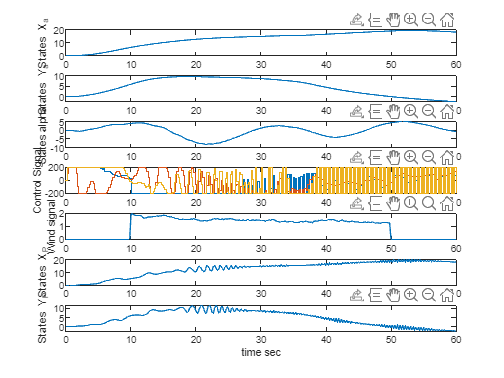

clf
t1 = linspace(0, 60, (60/h));
Xplayload = Xplant(1,:) + l.*sin(Xplant(4,:)).*cos(Xplant(5,:));
Yplayload = Xplant(2,:) + l.*sin(Xplant(4,:)).*sin(Xplant(5,:));



figure(1)
subplot(7,1,1)
plot(t1, Xplant(1,:));
ylabel("States X_a")
subplot(7,1,2)
plot(t1, Xplant(2,:));
ylabel("States Y_a")
subplot(7,1,3)
plot(t1, rad2deg(Xplant(4,:)));
ylabel("States alpha")
subplot(7,1,4)
stairs(t1, u(1,:));
hold on
stairs(t1, u(2,:));
stairs(t1, u(3,:));
ylabel("Control Signal")
hold off
subplot(7,1,5)
plot(t1, W);
ylabel("Wind signal")
subplot(7,1,6)
plot(t1, Xplayload);
ylabel("States X_P")
subplot(7,1,7)
plot(t1, Yplayload);
ylabel("States Y_P")
xlabel("time sec")


% subplot(5,1,5)
% stairs(t, duPlot(1,:));
% ylabel("\Delta u")
% xlabel("Time")

exportgraphics(gcf,'PresentationWindX10Y10NewMOREWINDMOREWIND!!45degress.pdf','ContentType','vector')